Individual Assignment #1

First step: Load the sung wav file and make spectrums of it.

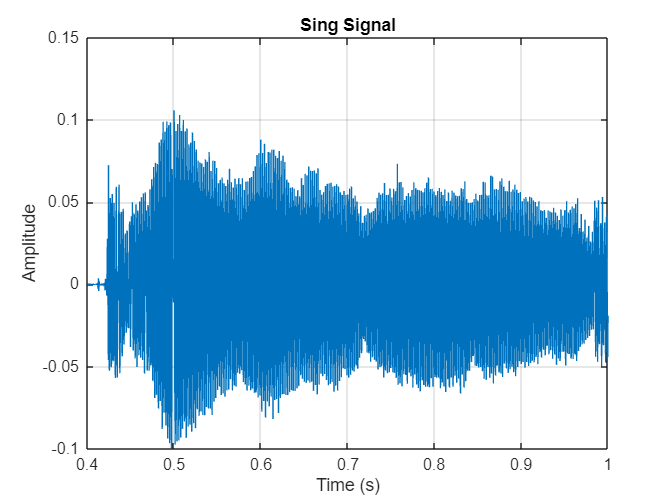

% Load the piano.wav file
path_2_wav = ['C:\Users\45422\Desktop\DSP\', filesep, 'Sounds', filesep];    % the path to the data
fname = 'iii.wav';                                 % a file name stored in a string variable
[sing_signal, fs] = audioread([path_2_wav,fname]); % Load the audio file and extract the sampling frequency

% Plot the time signal from 0 s to 1 s
t = (0:length(sing_signal)-1) / fs; % Time vector
figure;
plot(t, sing_signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sing Signal');
xlim([0.4 1]); % Limit the x-axis to 0 to 1 second
grid on;

fprintf('Estimated Fundamental Frequency: %.1f Hz\n', fs);

Estimated Fundamental Frequency: 16000.0 Hz


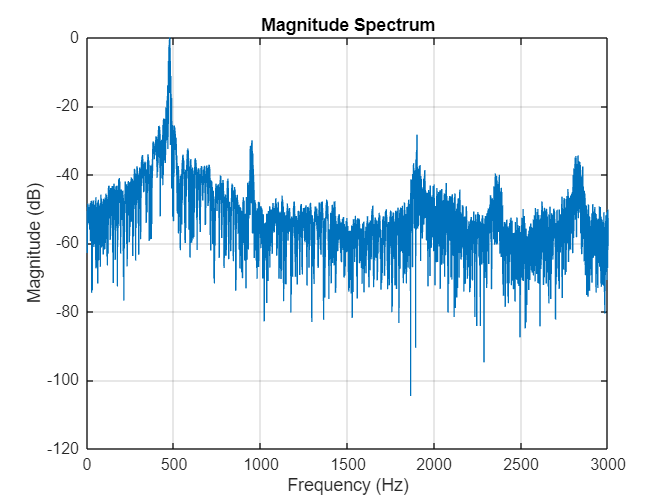


% Compute the Fourier Transform
Y = fft(sing_signal);
n = length(sing_signal);
f = (0:n-1) * (fs / n); % Frequency vector

% Compute the magnitude in dB
magnitude_dB = 20 * log10(abs(Y) / max(abs(Y)));

% Plot the magnitude spectrum
figure;
plot(f(1:floor(n/2)+1), magnitude_dB(1:floor(n/2)+1));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum');
xlim([0 3000]);
grid on;


% Estimate the fundamental frequency
[~, peakIndex] = max(magnitude_dB(1:floor(n/2)+1));
fundamental_frequency = f(peakIndex);

% Display the estimated fundamental frequency
fprintf('Estimated Fundamental Frequency: %.1f Hz\n', fundamental_frequency);

Estimated Fundamental Frequency: 475.6 Hz


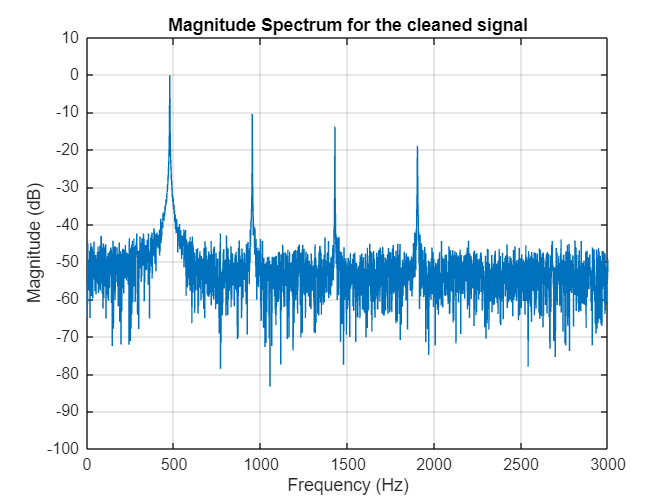

% Define the sampling frequency and time vector
fs = 44100; % Sampling frequency (44.1 kHz)
t = 0:1/fs:1; % Time vector for 1 second

% Create a synthetic signal with a fundamental frequency around 1000 Hz
fundamental_freq = 475.6;
sing_signal = sin(2 * pi * fundamental_freq * t);

% Add harmonics and noise to simulate a singing voice
harmonics = [2, 3, 4];
for k = harmonics
    sing_signal = sing_signal + (0.5 / k) * sin(2 * pi * k * fundamental_freq * t);
end
noise_level = 0.2;
sing_signal = sing_signal + noise_level * randn(size(t));

% Compute the Fourier Transform
Y = fft(sing_signal);
n = length(sing_signal);
f = (0:n-1) * (fs / n); % Frequency vector

% Compute the magnitude in dB
magnitude_dB = 20 * log10(abs(Y) / max(abs(Y)));

% Plot the magnitude spectrum
figure;
plot(f(1:floor(n/2)+1), magnitude_dB(1:floor(n/2)+1));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum for the cleaned signal');
xlim([0 3000]);
ylim([-100,10]);

grid on;


% Estimate the fundamental frequency
[~, peakIndex] = max(magnitude_dB(1:floor(n/2)+1));
fundamental_frequency = f(peakIndex);



Vi prøver nu at plotte dem sammen i det samme plot.

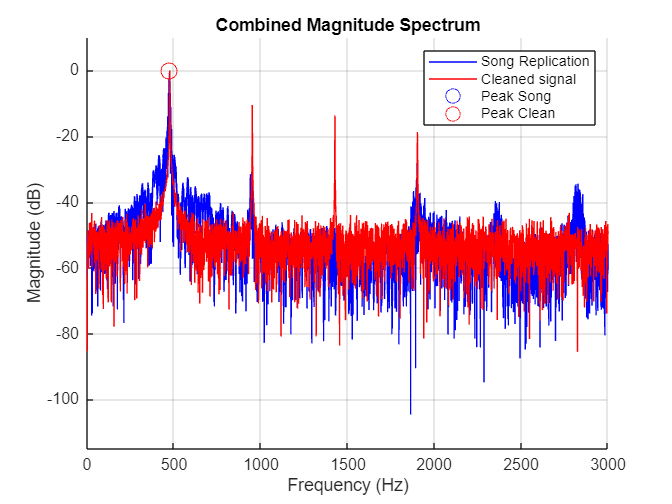

path_2_wav = ['C:\Users\45422\Desktop\DSP\', filesep, 'Sounds', filesep];    % the path to the data
fname = 'iii.wav';                                 % a file name stored in a string variable
[sing_signal, fs_sing] = audioread([path_2_wav,fname]); % Load the audio file and extract the sampling frequency

% Compute the Fourier Transform
Y_sing = fft(sing_signal);
n_sing = length(sing_signal);
f_sing = (0:n_sing-1) * (fs_sing / n_sing); % Frequency vector

% Compute the magnitude in dB
magnitude_dB_sing = 20 * log10(abs(Y_sing) / max(abs(Y_sing)));

% Define the sampling frequency and time vector
fs_clean = 44100; % Sampling frequency (44.1 kHz)
t_clean = 0:1/fs:1; % Time vector for 1 second

% Create a synthetic signal with a fundamental frequency around 1000 Hz
fundamental_freq = 475.6;
clean_signal = sin(2 * pi * fundamental_freq * t_clean);

% Add harmonics and noise to simulate a singing voice
harmonics = [2, 3, 4];
for k = harmonics
    clean_signal = clean_signal + (0.5 / k) * sin(2 * pi * k * fundamental_freq * t_clean);
end
noise_level = 0.2;
clean_signal = clean_signal + noise_level * randn(size(t_clean));

% Compute the Fourier Transform
Y_clean = fft(clean_signal);
n_clean = length(clean_signal);
f_clean = (0:n_clean-1) * (fs_clean / n_clean); % Frequency vector

% Compute the magnitude in dB
magnitude_dB_clean = 20 * log10(abs(Y_clean) / max(abs(Y_clean)));

figure;
hold on;
plot(f_sing(1:floor(n_sing/2)+1), magnitude_dB_sing(1:floor(n_sing/2)+1), 'b', 'DisplayName', 'Song Replication');
plot(f_clean(1:floor(n_clean/2)+1), magnitude_dB_clean(1:floor(n_clean/2)+1), 'r', 'DisplayName', 'Cleaned signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Combined Magnitude Spectrum');
xlim([0 3000]);
ylim([-115 10]);
grid on;

% Highlight the peaks
[~, peakIndex1] = max(magnitude_dB_sing(1:floor(n_sing/2)+1));
peakFreq1 = f_sing(peakIndex1);
[~, peakIndex2] = max(magnitude_dB_clean);
peakFreq2 = f_clean(peakIndex2);
plot(peakFreq1, magnitude_dB_sing(peakIndex1), 'bo', 'MarkerSize', 10, 'DisplayName', 'Peak Song');
plot(peakFreq2, magnitude_dB_clean(peakIndex2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Peak Clean');

legend('show');
hold off;